x = 0 : 0.01 : 2*pi

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y = sin(x)

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


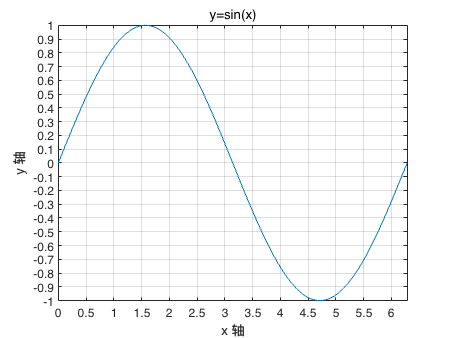

%% 创建画布
figure

%% 绘制图像
plot(x, y)

%% 添加标题
title('y=sin(x)')

%% 添加自定义 x、y 刻度
xticks(0 : 0.5 : 2*pi)
yticks(-1 : 0.1 : 1)

%% x、y 轴说明
xlabel('x 轴')
ylabel('y 轴')

%% 设置图像显示的起始值和结束值
xlim([0 2*pi])

%% 添加网格显示
grid('on')

## 绘制多个图像

x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


y1 =          0    0.0500    0.0998    0.1494    0.1987    0.2474    0.2955    0.3429    0.3894    0.4350    0.4794    0.5227    0.5646    0.6052    0.6442    0.6816    0.7174    0.7513    0.7833    0.8134    0.8415    0.8674    0.8912    0.9128    0.9320    0.9490    0.9636    0.9757    0.9854    0.9927    0.9975    0.9998    0.9996    0.9969    0.9917    0.9840    0.9738    0.9613    0.9463    0.9290    0.9093    0.8874    0.8632    0.8369    0.8085    0.7781    0.7457    0.7115    0.6755    0.6378


y2 =     1.0000    0.9988    0.9950    0.9888    0.9801    0.9689    0.9553    0.9394    0.9211    0.9004    0.8776    0.8525    0.8253    0.7961    0.7648    0.7317    0.6967    0.6600    0.6216    0.5817    0.5403    0.4976    0.4536    0.4085    0.3624    0.3153    0.2675    0.2190    0.1700    0.1205    0.0707    0.0208   -0.0292   -0.0791   -0.1288   -0.1782   -0.2272   -0.2756   -0.3233   -0.3702   -0.4161   -0.4611   -0.5048   -0.5474   -0.5885   -0.6282   -0.6663   -0.7027   -0.7374   -0.7702


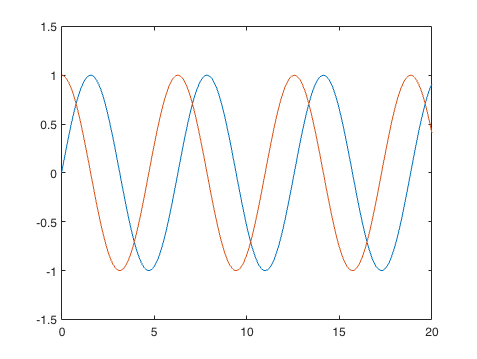

x = 0 : 0.05 : 30

y1 = sin(x)
y2 = cos(x)

figure

%% 【重点】绘制多个图像

plot(x, y1, x, y2)

%% 【重点】设置 xy 的显示范围
axis([0 20 -1.5 1.5])

## 条形图

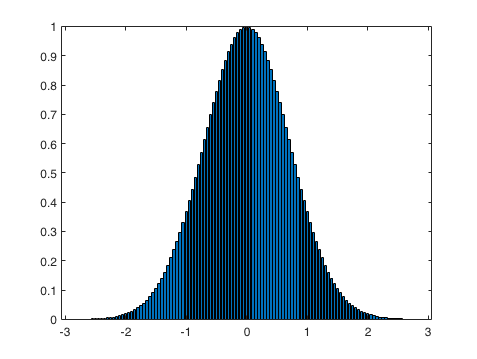

t = -3 : 0.05 : 3;
p = exp(-t .* t);
bar(t, p)

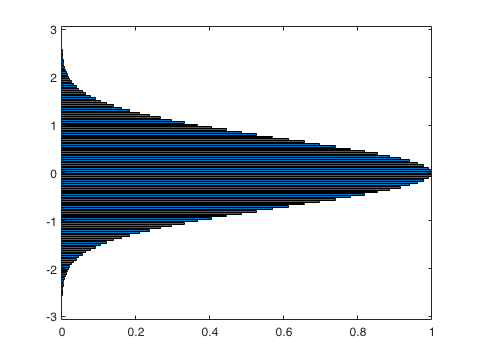

barh(t, p)

## 极坐标图

theta = 0 : 0.01 : 2*pi;
radi = abs(sin(7*theta) .* cos(10*theta))

radi =          0    0.0696    0.1368    0.1991    0.2545    0.3009    0.3365    0.3600    0.3701    0.3662    0.3481    0.3158    0.2698    0.2112    0.1412    0.0614    0.0263    0.1196    0.2163    0.3140    0.4101    0.5023    0.5882    0.6658    0.7330    0.7883    0.8304    0.8584    0.8718    0.8704    0.8546    0.8251    0.7830    0.7298    0.6672    0.5972    0.5222    0.4444    0.3664    0.2904    0.2190    0.1542    0.0982    0.0526    0.0189    0.0018    0.0088    0.0018    0.0190    0.0530


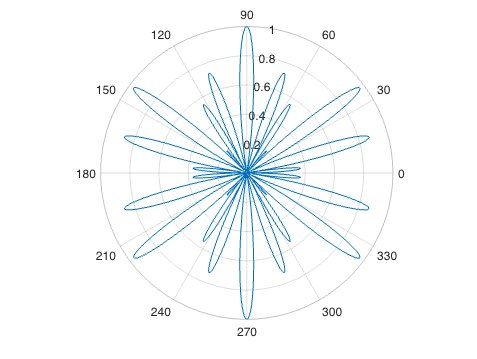


% 参数：弧度和半径
polarplot(theta, radi)

## 散点图

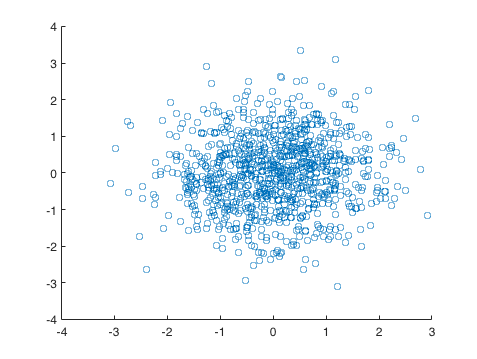

% 生成符合正态分布的 1000 行、1 列的数
height = randn(1000, 1);
weight = randn(1000, 1);
scatter(height, weight)